Playing hod_m.wav at 24000 Hz with duration 0.22 seconds and 5380 samples


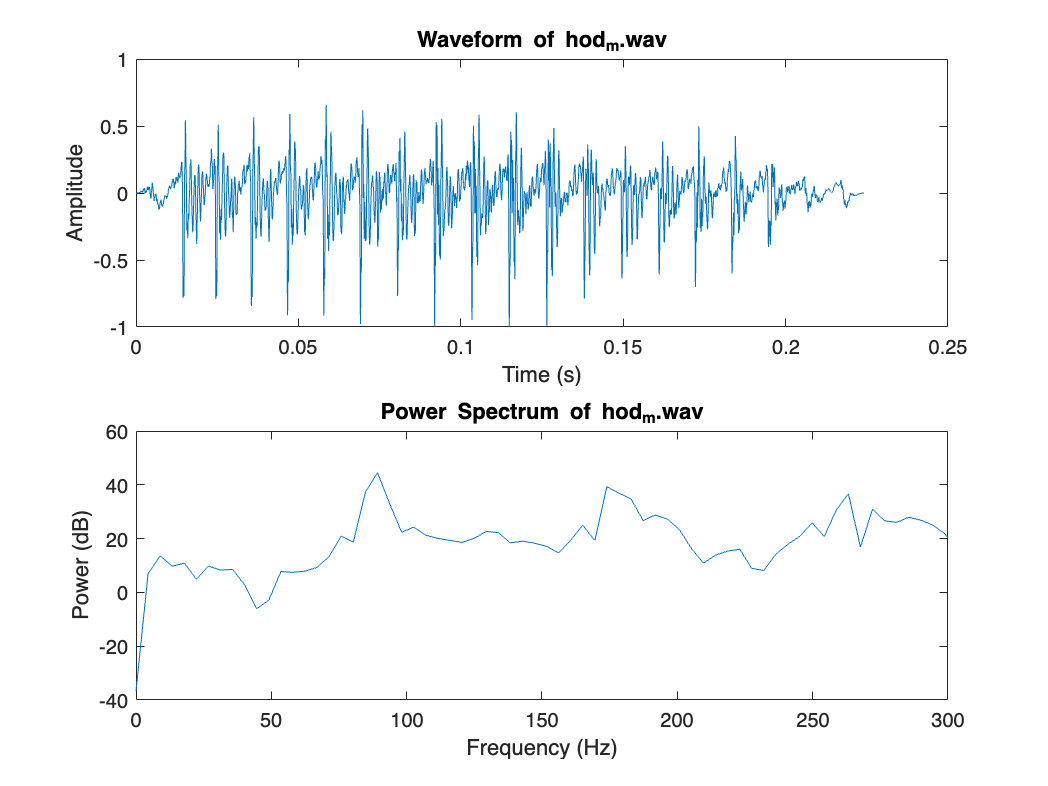

filename = 'hod_m.wav';
[audio, fs, duration, numSamples] = playAudio(filename);

Window Size: 480 samples (20.00 ms)
Overlap: 360 samples (15.00 ms)
FFT Length (N): 2048

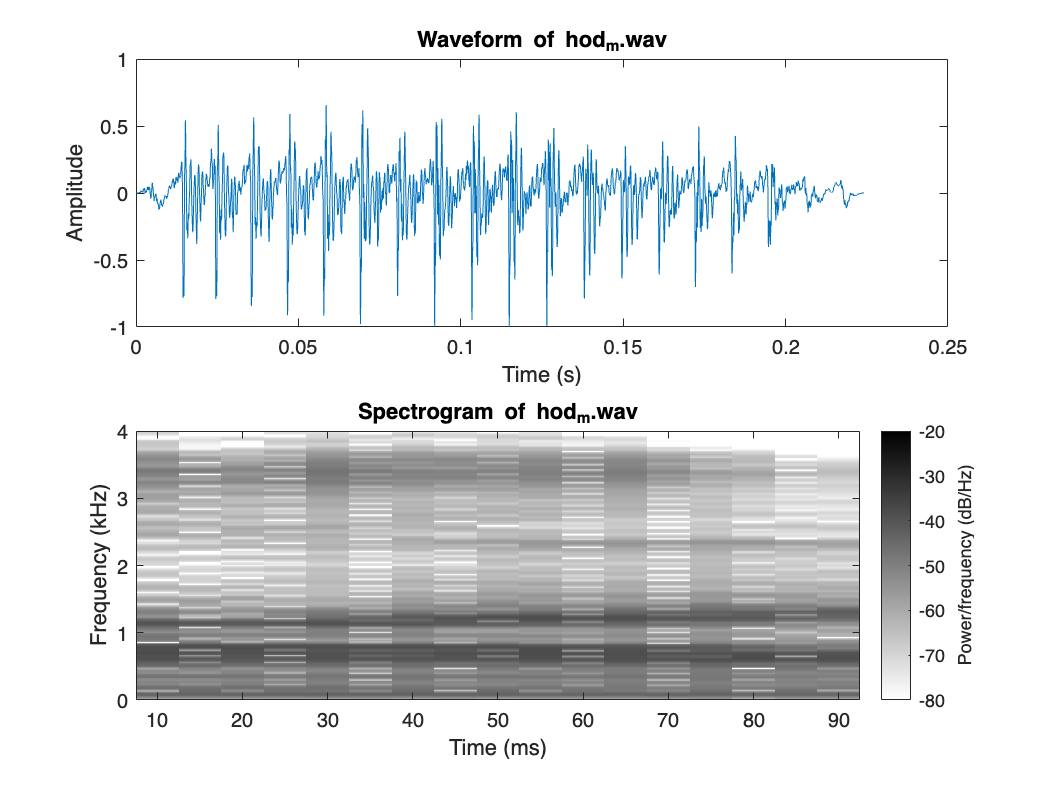

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, filename);
plotSpectrogram(segment, fs, filename);

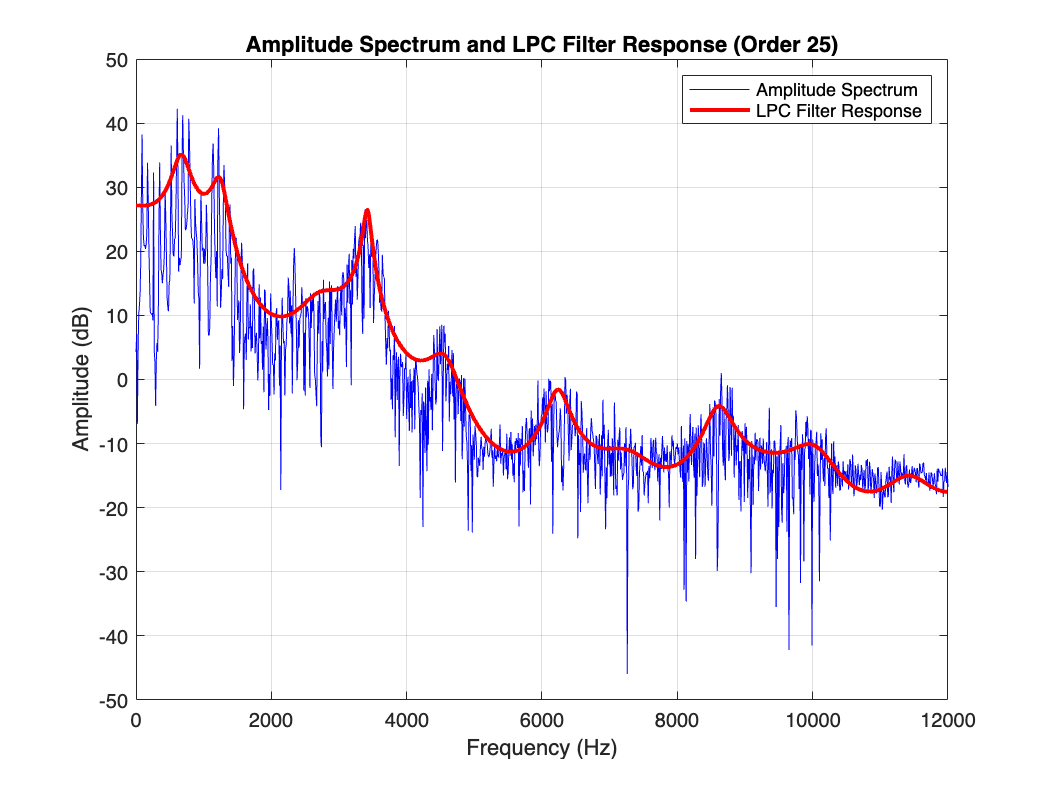

lpcOrder = 25;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 671.18 Hz
F2: 1245.79 Hz
F3: 2713.61 Hz


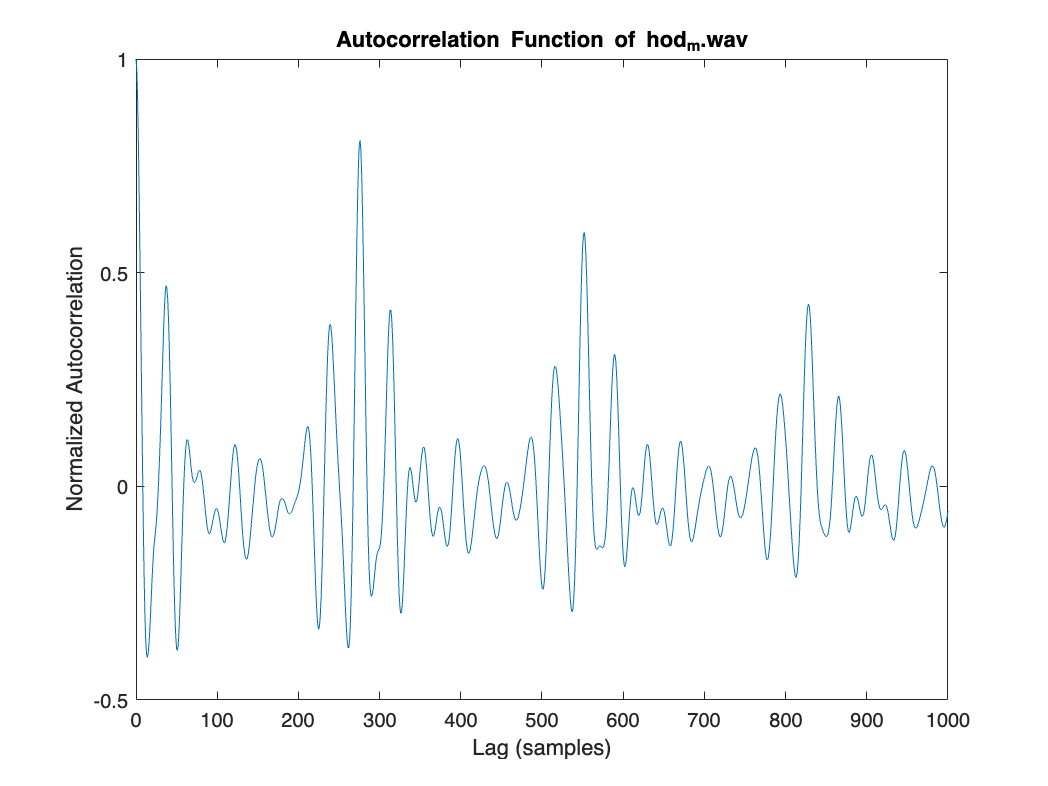

Estimated F0 using autocorrelation: 86.96 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs, filename);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 90.00 Hz


f0 = mean(pitch(segment, fs));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 87.08 Hz


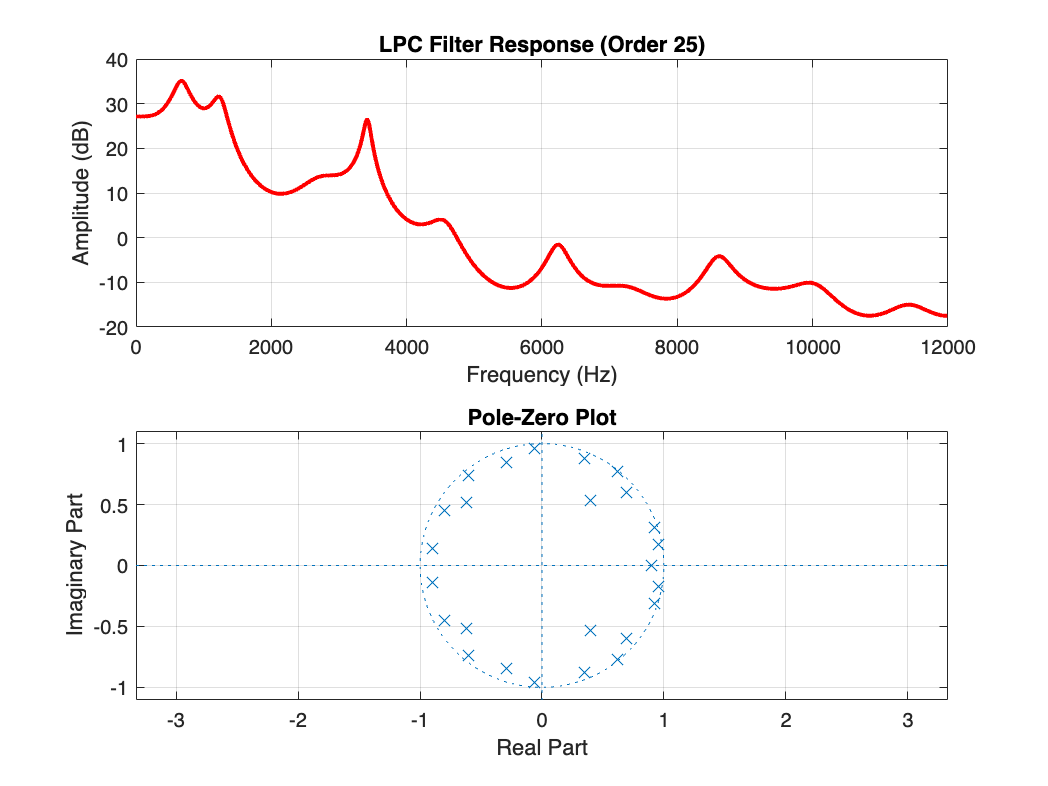

plotLPCPoleZero(segment, fs, lpcOrder);

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1, filename);

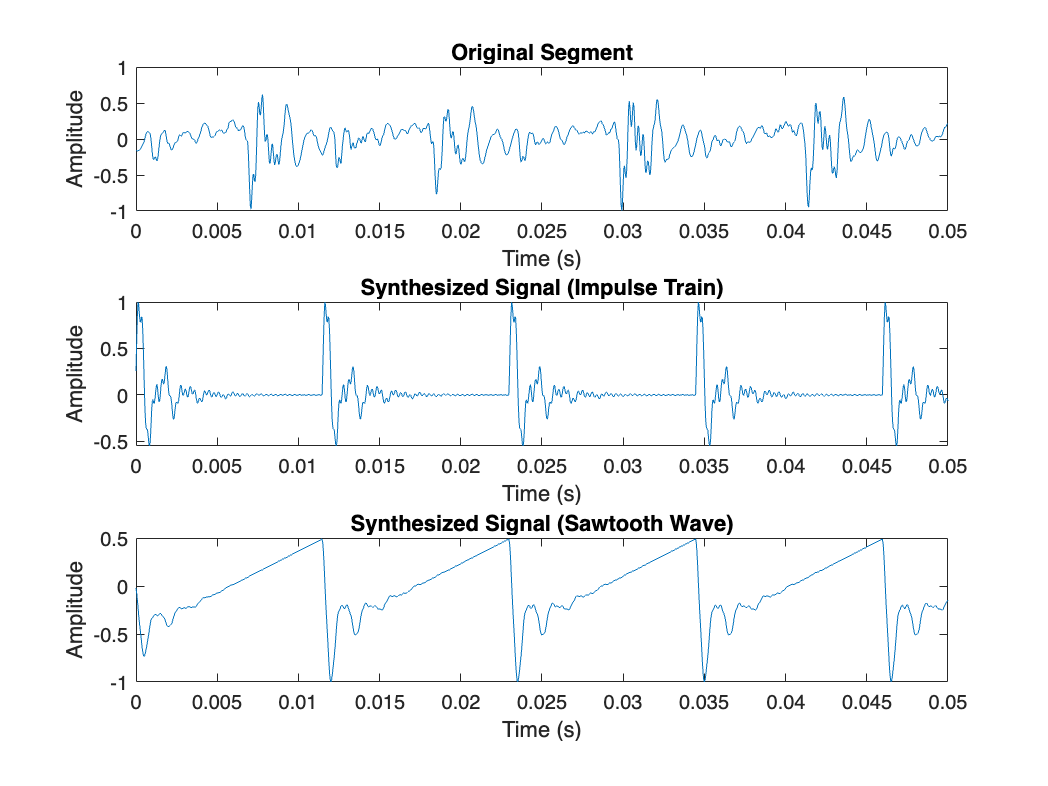

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);

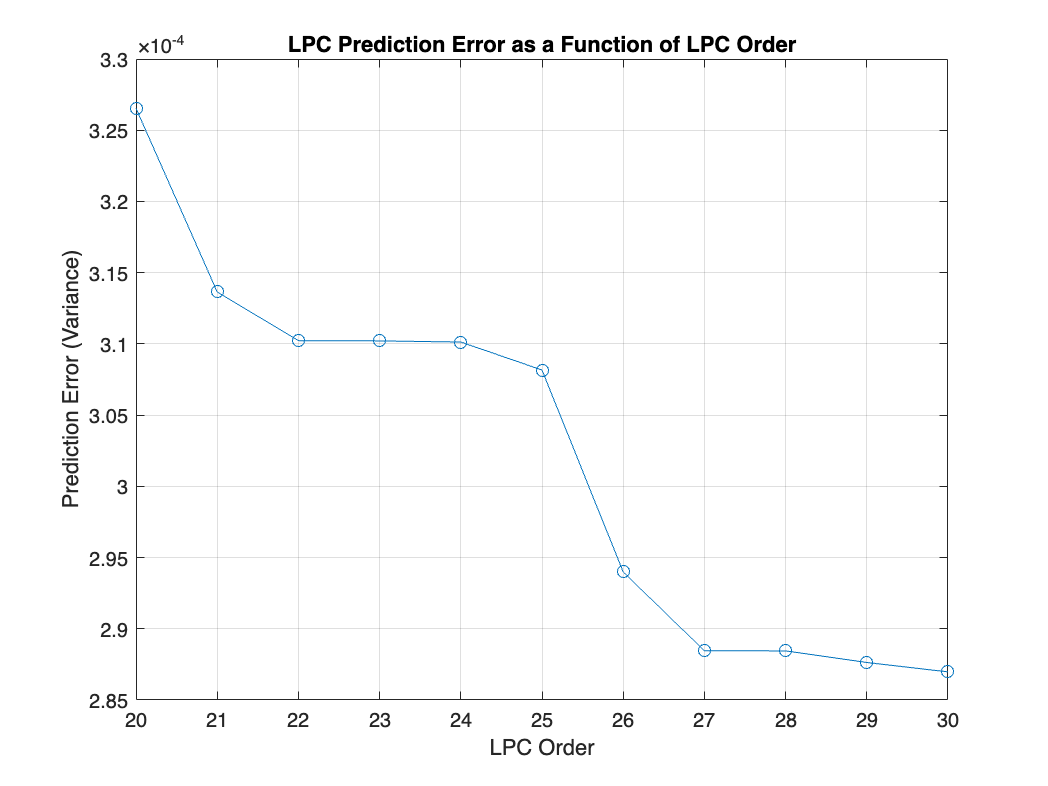

orderAnalysis(segment, 20, 30)

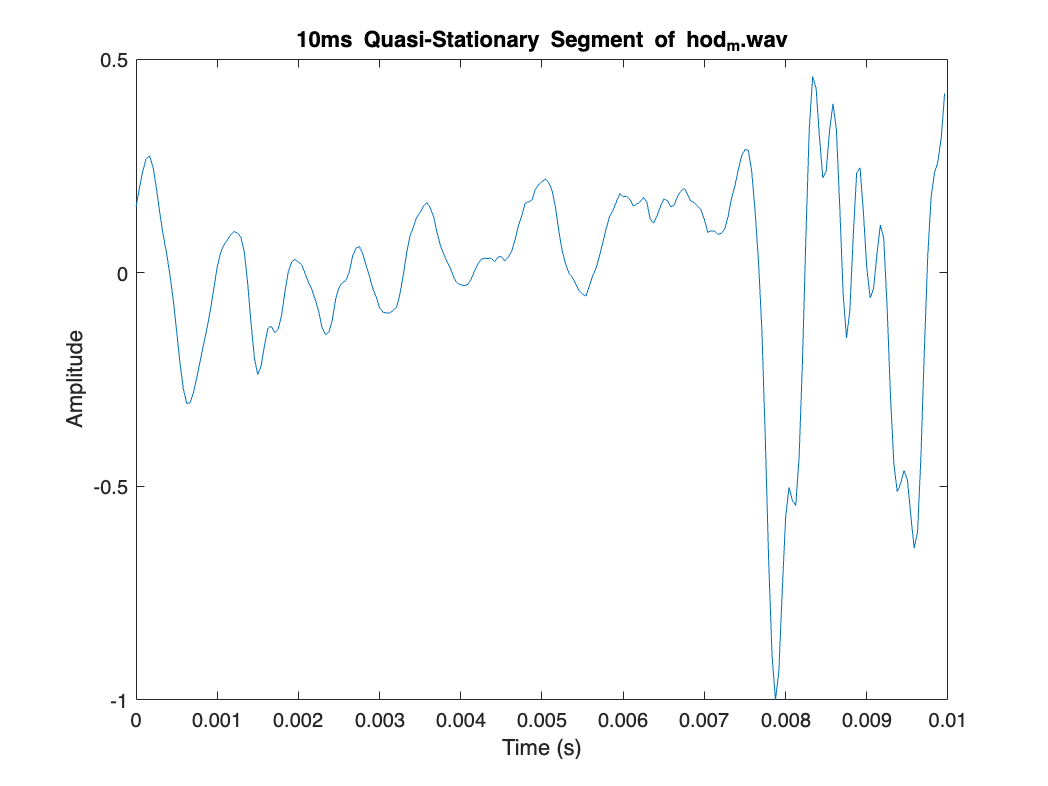

segmentAnalysis(audio, fs, 30, filename)

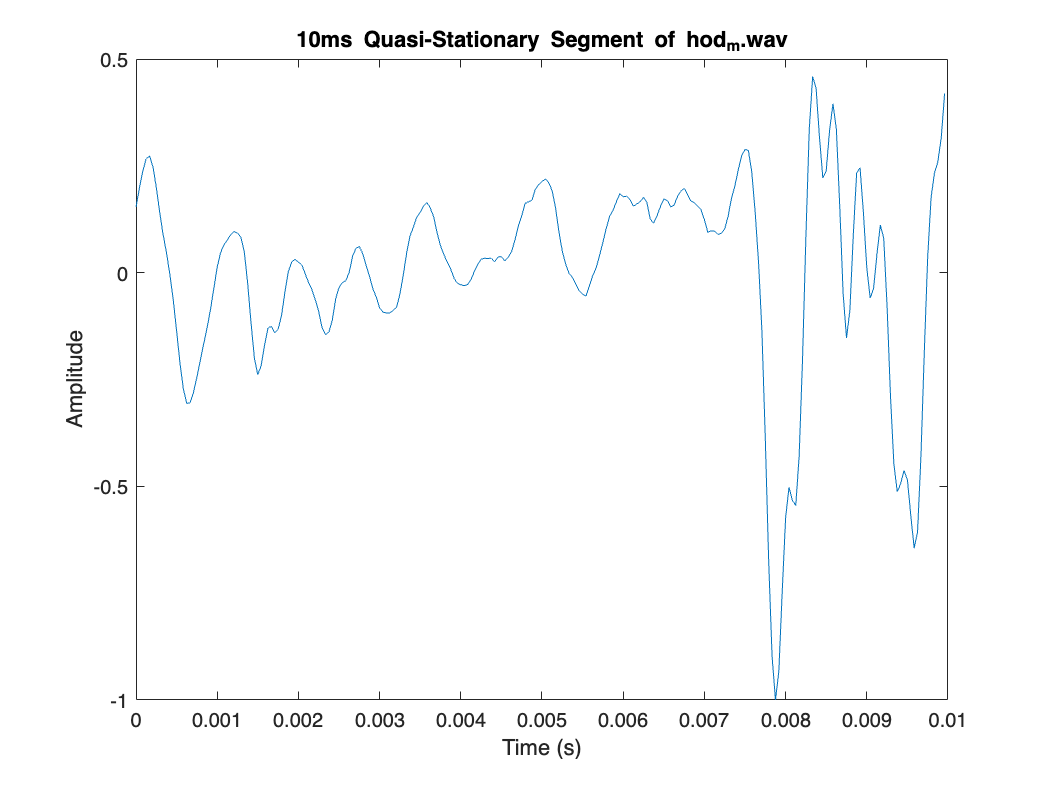

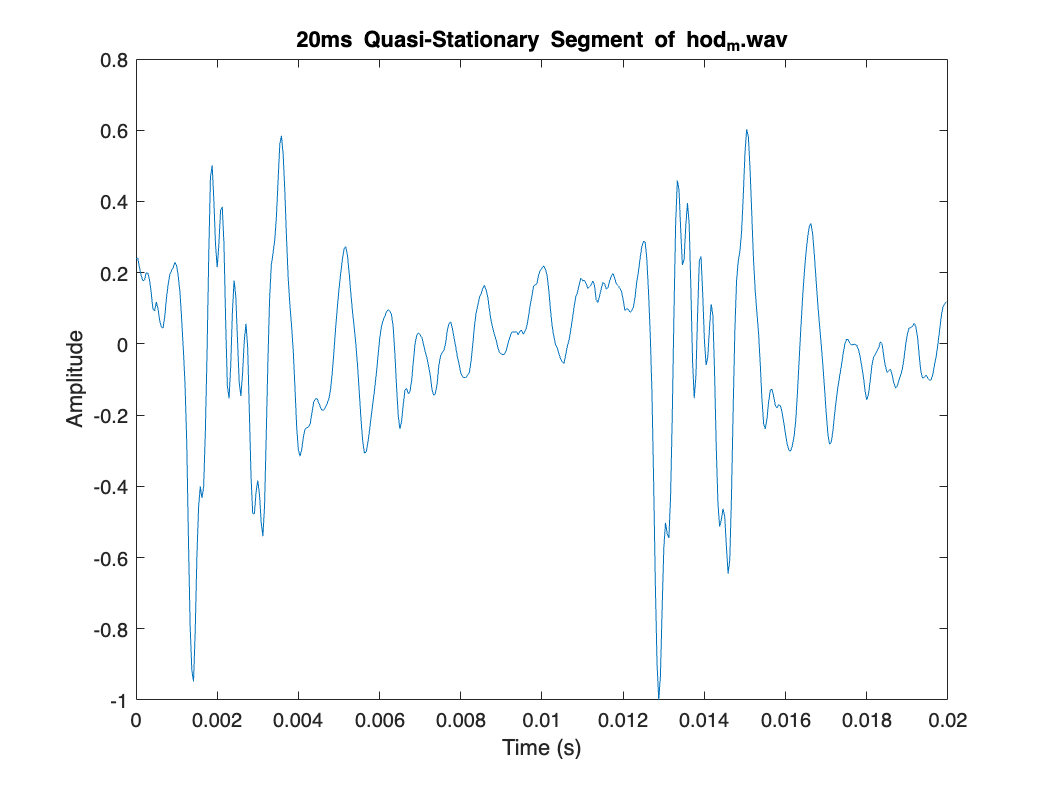

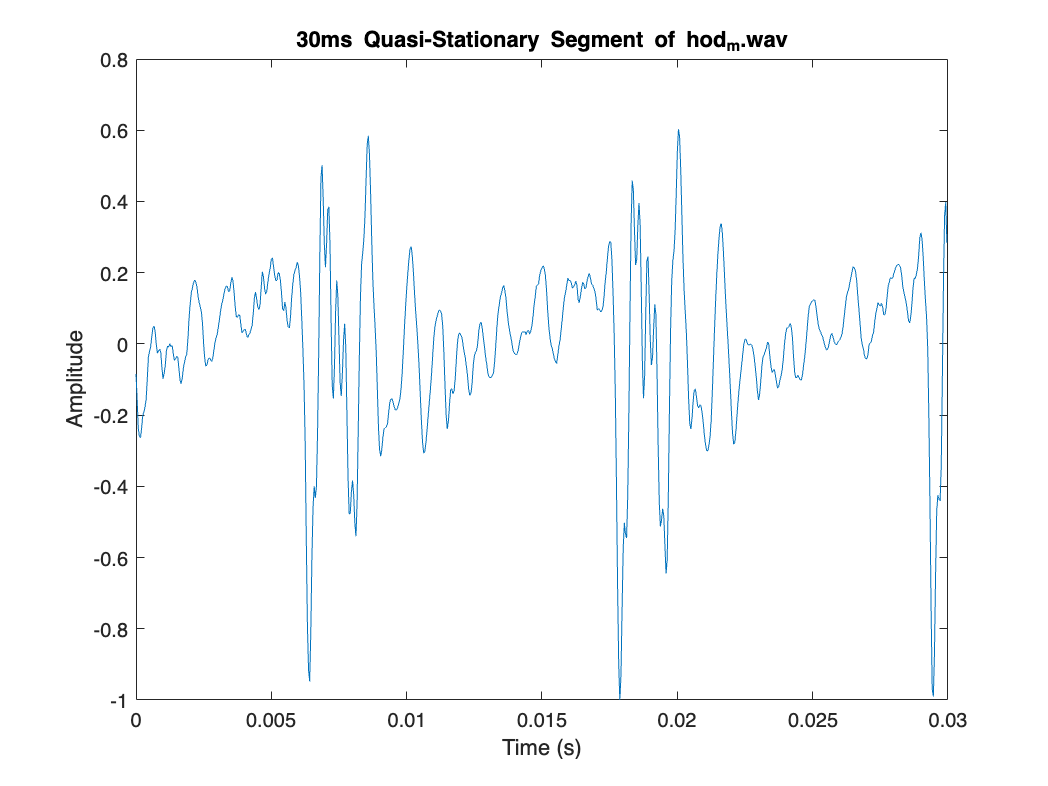

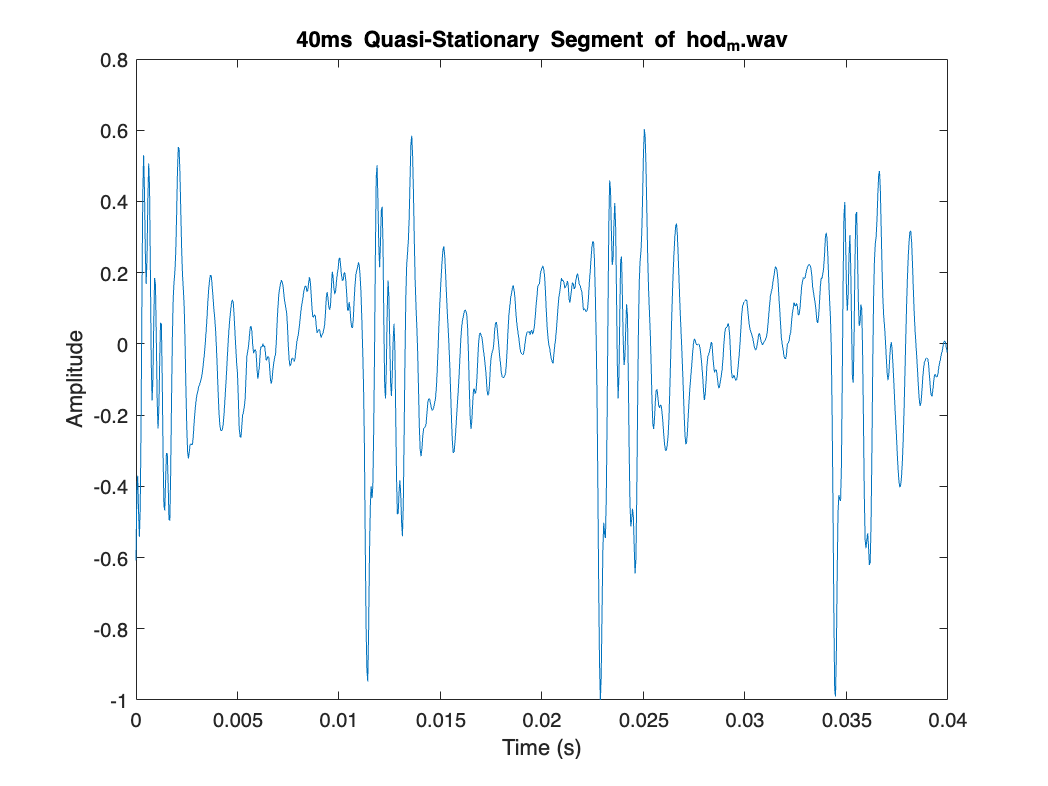

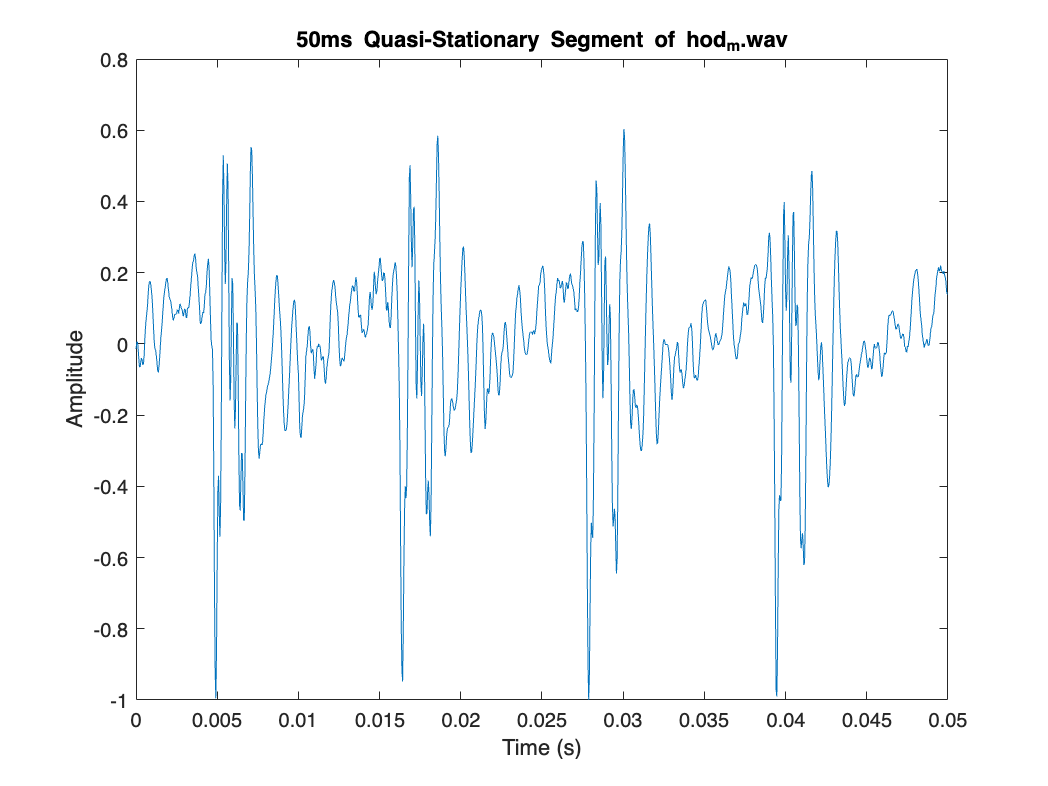

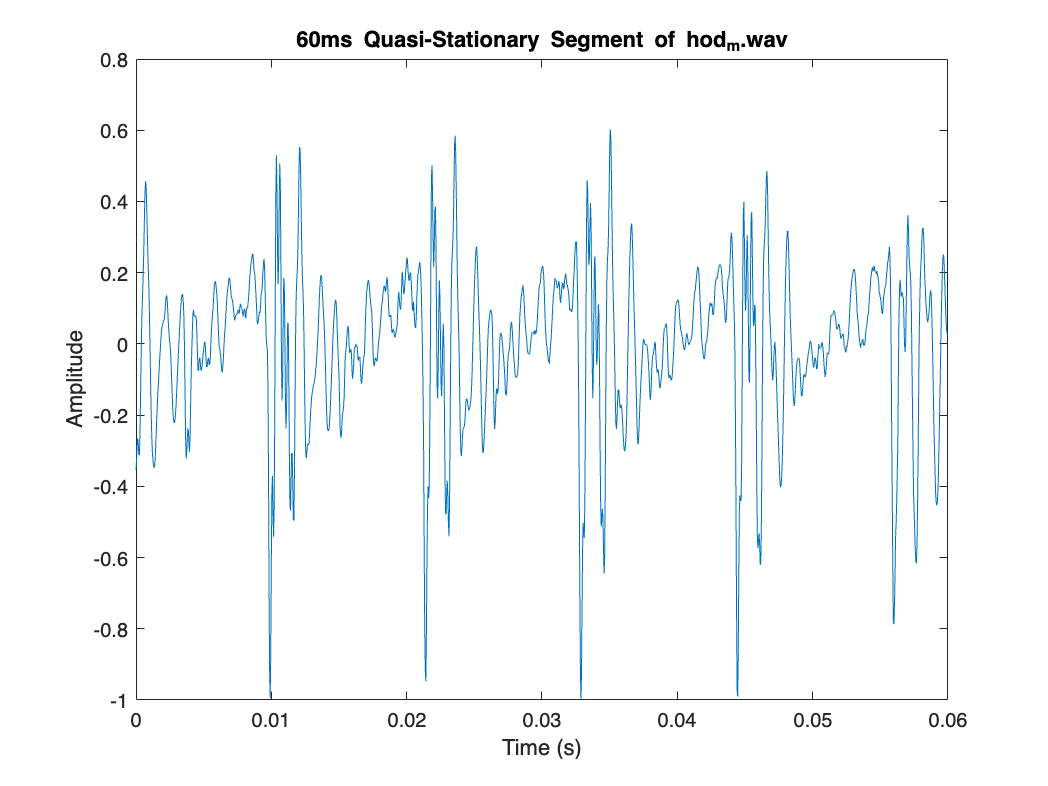

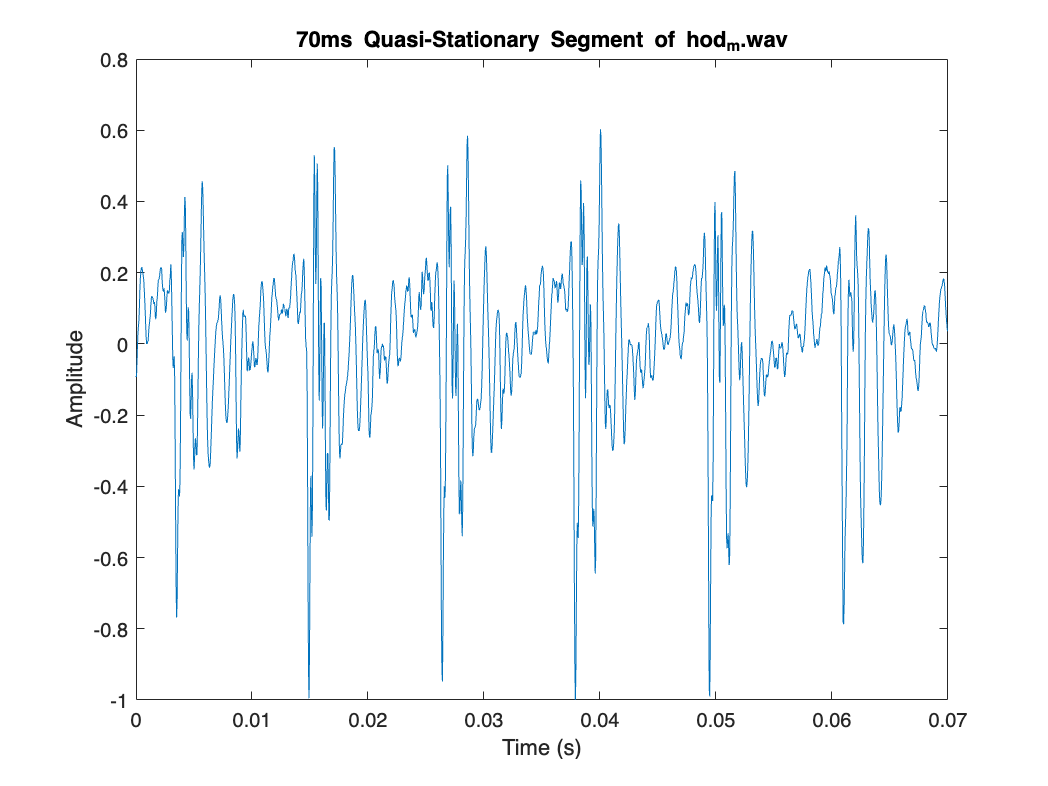

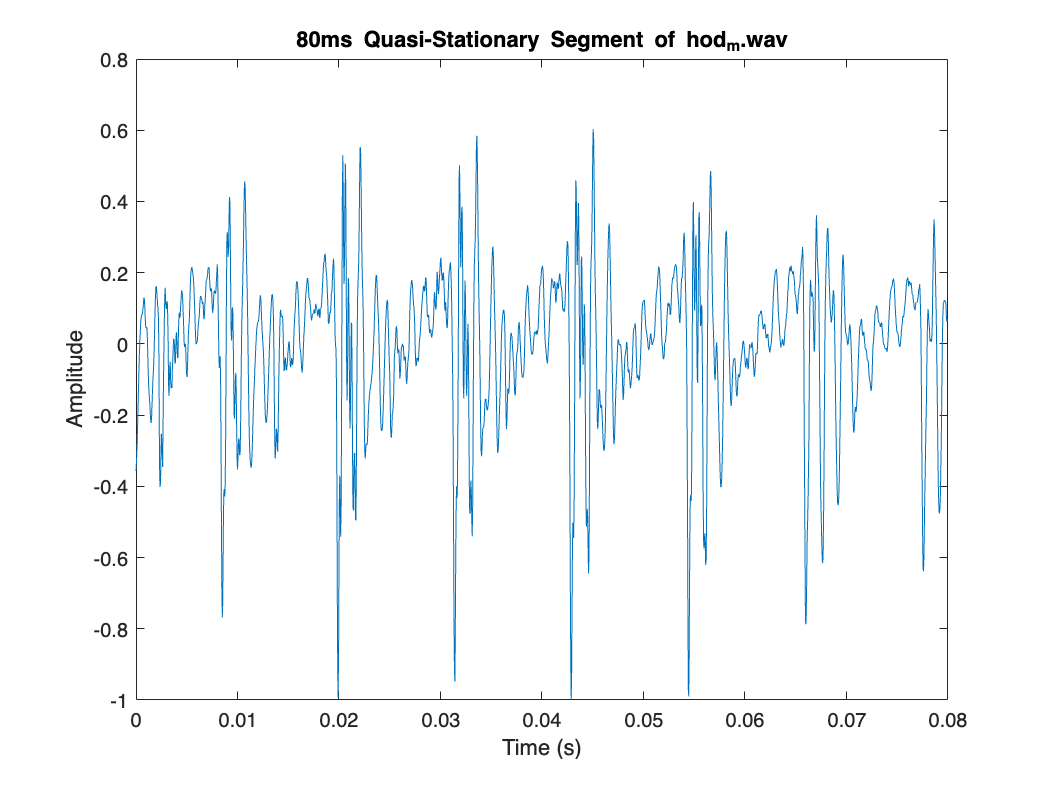

orderSegmentAnalysis(audio, fs, filename)